# Critical Path Method

Critical Path Method (CPM) is a network-based method designed to assist in the planning, scheduling, and control of projects. A project is defined as a collection of interrelated activities with each activity consuming time and resources. The objective of CPM is to devise analytic tools for scheduling the activities. **Figure 1 **summarizes the steps of the techniques. First, we define the activities of the project, their precedence relationships, and their time requirements. Next, the precedence relationships among the activities are modeled as a network. The third step involves specific computations for developing the time schedule. During the actual execution phase, execution of the activities may not proceed as planned, in the sense that some of the activities may be expedited or delayed. When this happens, the schedule is updated to reflect the realities on the ground. This is the reason for including a feedback loop in **Figure 1**.

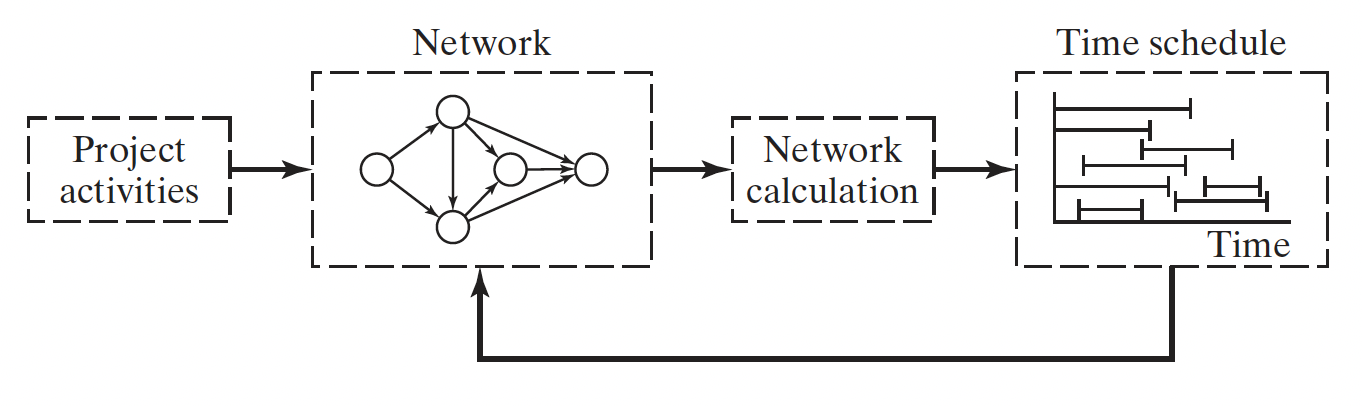

**Figure 1: **Phases for project planning with CPM

## Network Representation

Each activity is represented by an arc pointing in the direction of progress in the project. The nodes of the network establish the precedence relationships among the different activities. Three rules are available for constructing the network.

**Rule 1. **Each activity is represented by one, and only one, arc.

**Rule 2.** Each activity must be identified by two distinct end nodes.

**Rule 3. **To maintain the correct precedence relationships, the following questions must be answered as each activity is added to the network:

- What activities immediately precede the current activity?

- What activities immediately follow the current activity?

- What activities are concurrent with the current activity?

A **dummy activity** can be used to provide unique representation of two concurrent activities, A and B. By definition, a (dashed) dummy activity consumes no time or resources. Inserting a dummy activity in one of the four ways shown in** Figure 2** maintains the concurrence of A and B and provides unique end nodes for the two activities to satisfy **Rule 2**. 

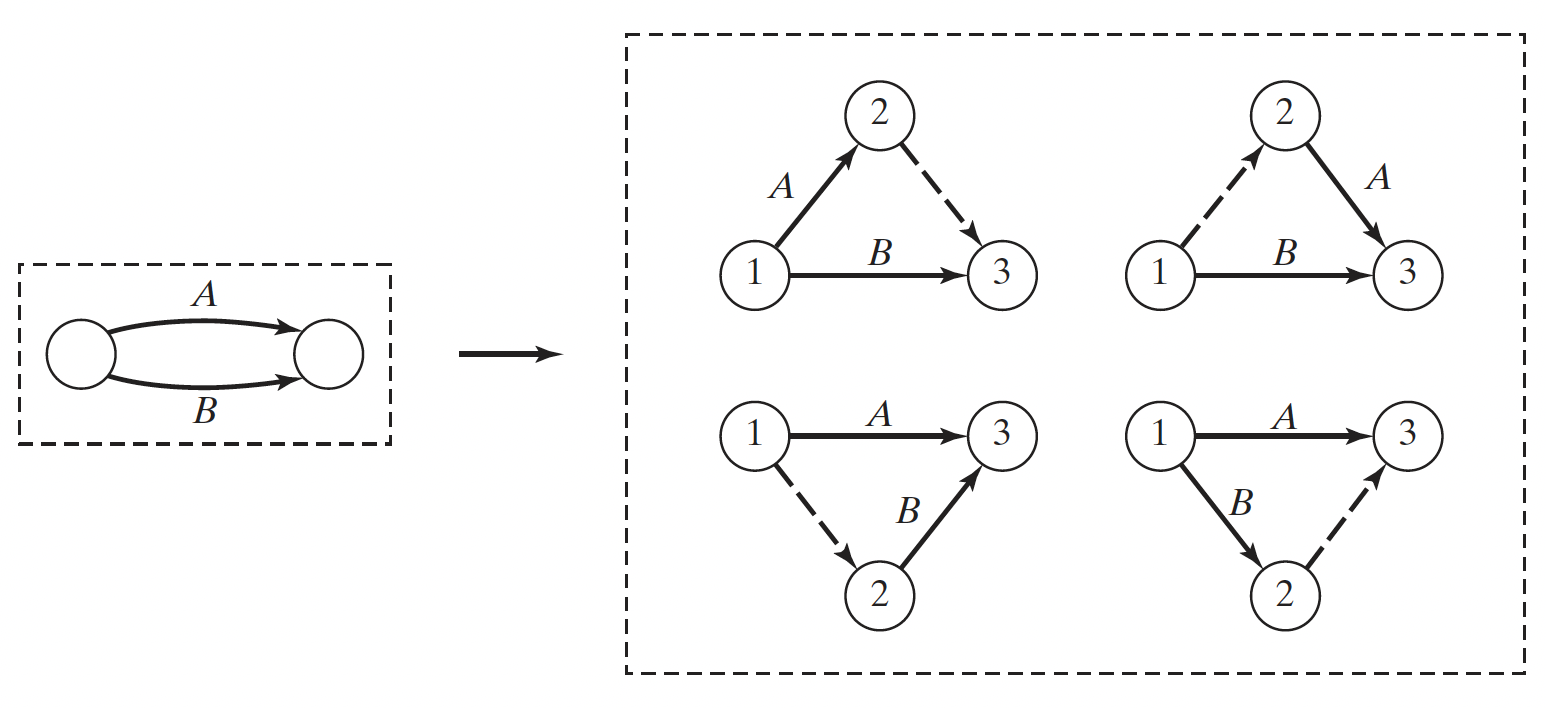

**Figure 2: **Use of dummy activity to produce unique representation of concurrent activities

The answers to three questions of **Rule 3** may require the use of dummy activities to ensure correct precedence among the activities. For example, consider the following segment of a project:

- Activity C starts immediately after activities A and B have been completed.

- Activity E can start after activity B is completed.

Part (a) of **Figure 3** shows the incorrect representation of the precedence relationship because it requires both A and B to be completed before E can start. In part (b), the use of a dummy activity rectifies the situation.

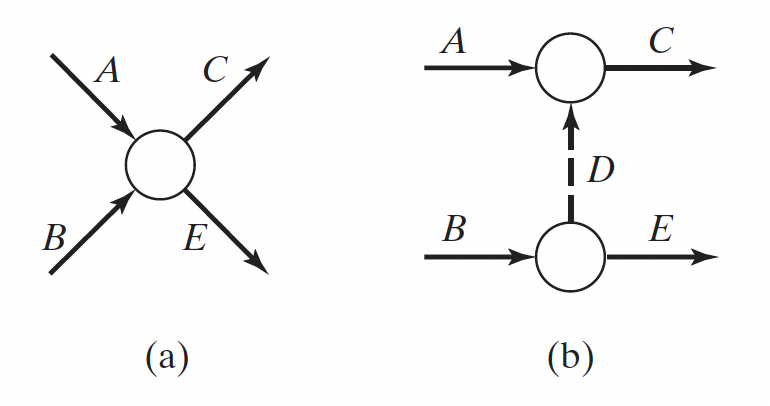

**Figure 3: **Use of dummy activity to ensure correct precedence relationship

### Example 1

A publisher has a contract with an author to publish a textbook. The author submits a hard copy and a computer file of the manuscript. The (simplified) activities associated with the production of the textbook are summarized in the following table:

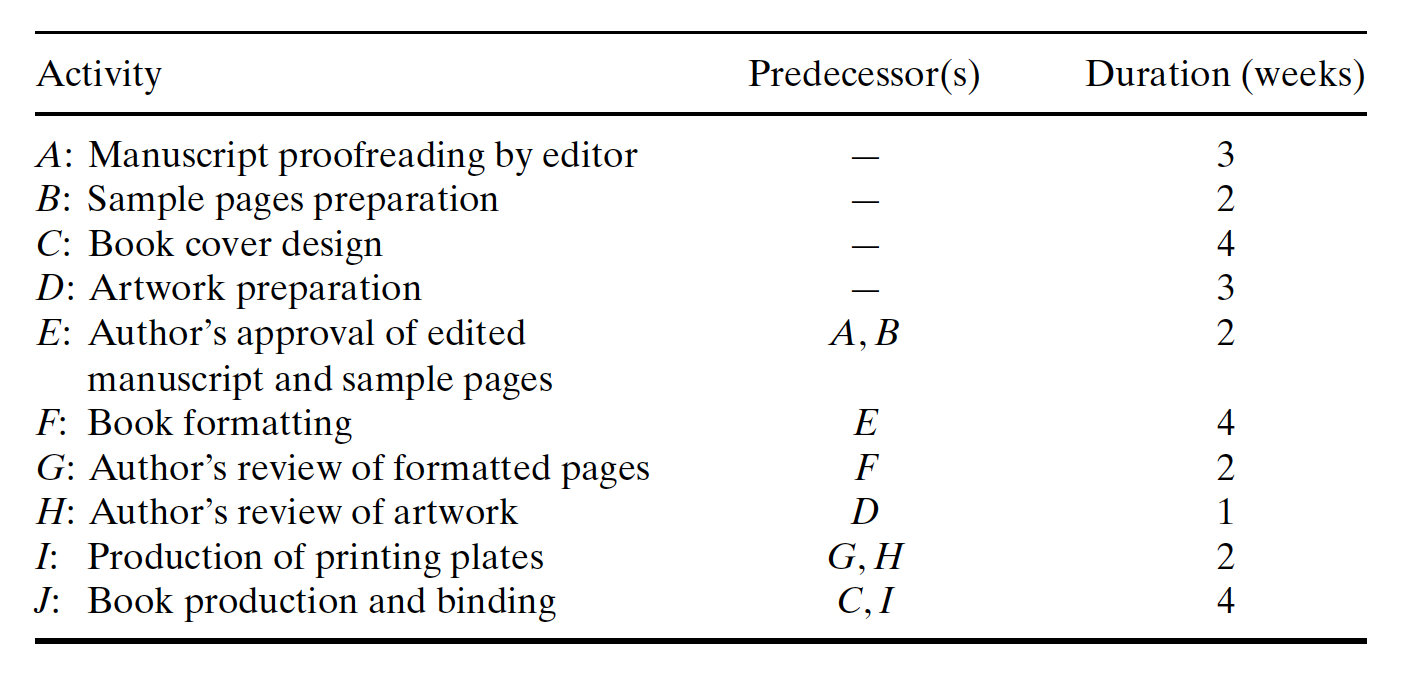

**Figure 4** provides the project network. Dummy activity (2, 3) produces unique end nodes for concurrent activities A and B. It is convenient to number the nodes in ascending order pointing toward the direction of progress in the project.

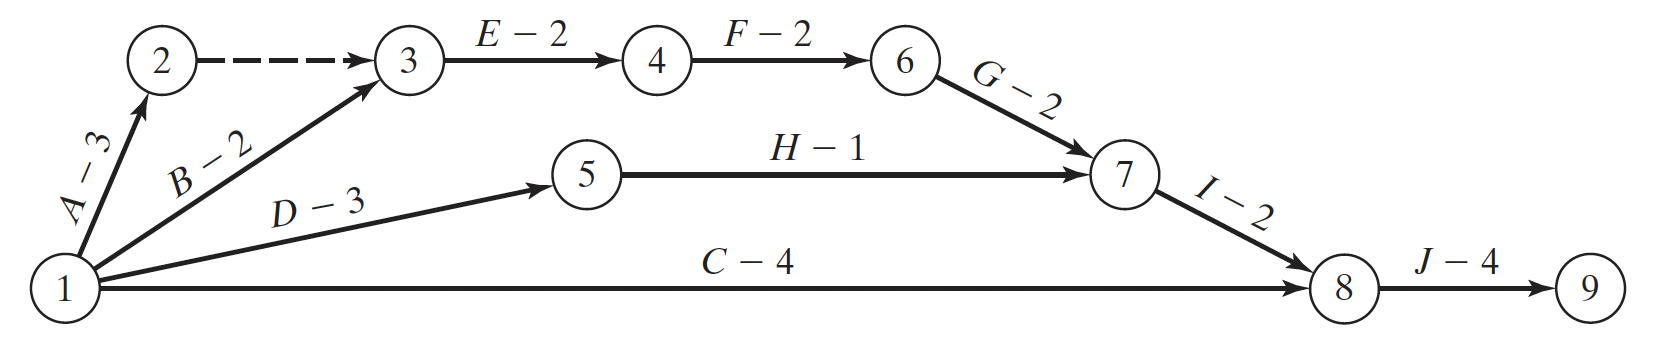

**Figure 4: **Project network for Example 1

### **Example 2**

Construct the project network comprised of activities A to M with the following precedence relationships:

(a) A, B, and C, the first activities of the project, can be executed concurrently.

(b) A and B precede D.

(c) B precedes E, F, and H.

(d) F and C precede G and M.

(e) E and H precede I and J.

(f) C, D, F, and J precede K.

(g) K and M precedes L.

(h) I, G, and L are the terminal activities of the project.

## Linear programming Formulation of CPM

The CPM model seeks the longest path between the start and finish nodes of the project network. Its formulation as an LP is thus similar to the LP of **the shortest-route model**. The only difference is that the objective function is maximized instead of minimized.

Define

$x_{ij}$ = Amount of flow in activity $(i, j)$, for all defined $i$ and $j$

$D_{ij}$ = Duration of activity $(i, j)$, for all defined $i$ and $j$

Thus, the objective function of the linear program becomes

 Maximize $z=\sum_{i,j} D_{\mathrm{ij}} x_{\mathrm{ij}}$

For each node, there is one constraint that represents the conservation of flow:

Total input flow = Total output flow

All the variables, $x_{ij}$, are nonnegative.

### **Example 3**

Determine the critical path for the project network in **Figure 5**.

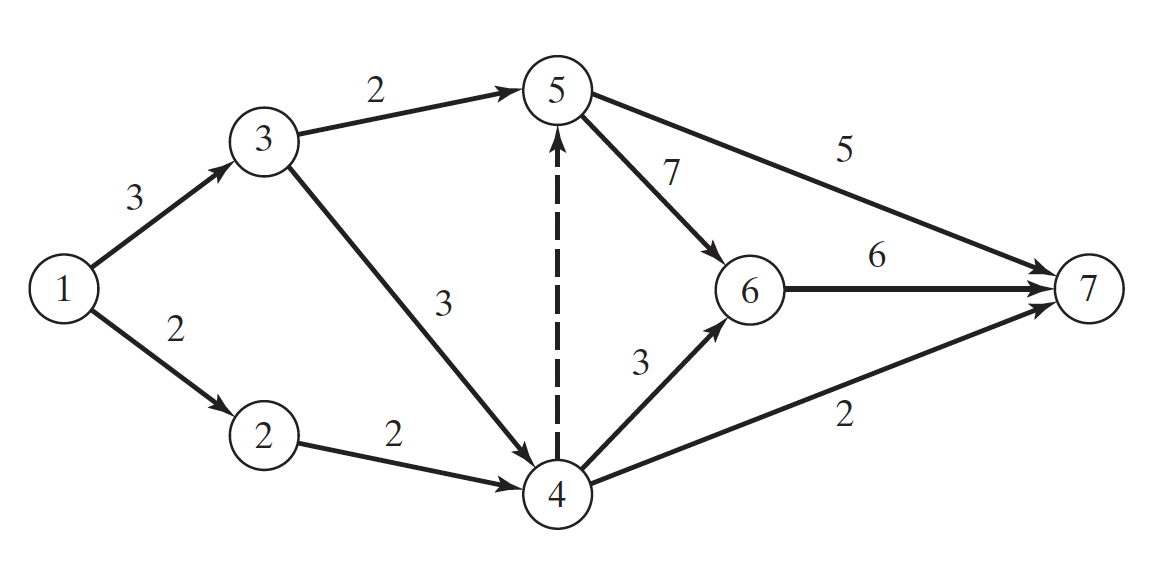

**Figure 5: **Project networks for Example 3

#### **Solve as a LInear Programming (LP)**

% Example 3 (LP)

f1   = -1*[3; 3; 2; 3; 2; 0; 3; 2; 7; 5; 6];
A1   = [];
Aeq1 = [-1	-1	0	0	0	0	0	0	0	0	0
        1	0	-1	0	0	0	0	0	0	0	0
        0	1	0	-1	-1	0	0	0	0	0	0
        0	0	1	1	0	-1	-1	-1	0	0	0
        0	0	0	0	1	1	0	0	-1	-1	0
        0	0	0	0	0	0	1	0	1	0	-1
        0	0	0	0	0	0	0	1	0	1	1];
b1   = [];
beq1 = [-1; 0; 0; 0; 0; 0; 1];
lb1  = zeros(11,1);
ub1  = [];

[x1, fval1, exitflag1, output1, lambda1] = linprog(f1, A1, b1, Aeq1, beq1, lb1, ub1);


Optimal solution found.




% Display the results of the optimization
disp('Optimal solution (x1):');

Optimal solution (x1):


disp(x1);

     0
     1
     0
     1
     0
     1
     0
     0
     1
     0
     1



disp('Maximum project duration (fval1):');

Maximum project duration (fval1):


disp(-fval1);

    19



#### **Solve as a Shortest-Route Problem**

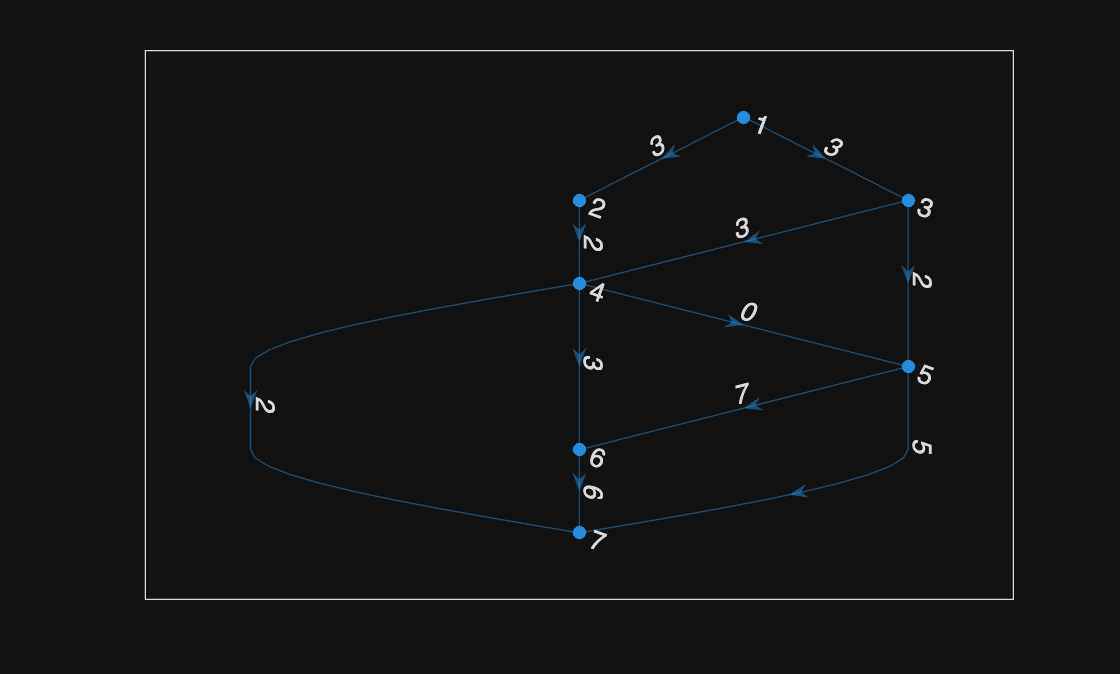

% Example 3 (Shortest-Route)

% Create and plot a graph with weighted edges
s1      =   [1;   1;   2;   3;   3;   4;   4;   4;   5;   5;   6];
t1      =   [2;   3;   4;   4;   5;   5;   6;   7;   6;   7;   7];
wght1   =   [3;   3;   2;   3;   2;   0;   3;   2;   7;   5;   6];
G1      = digraph(s1,t1,wght1);
plot(G1,'EdgeLabel',G1.Edges.Weight);

% Negate edge weights to find the longest path using shortestpath
G1_neg = G1;
G1_neg.Edges.Weight = -G1_neg.Edges.Weight;

% Find the longest path between nodes 1 and 7, 
% and specify two outputs to also return the length of the path
[P1,d1] = shortestpath(G1_neg,1,7);

% Display the longest path and its length
disp('The longest path from node 1 to node 7 is:');

The longest path from node 1 to node 7 is:


disp(P1);

     1     3     4     5     6     7



disp('The project duration is:');

The project duration is:


disp(-d1);

    19



`End-of-file`

`Pongsun B.`

`2025-10-30`